% sensor to distance in meters (curve fit)
d = @(x) 1.3501.*exp(-0.0038.*x);
% microsecond servo values to angles
a = @(x) ((x-544)./2400).*180 - 40; %the -40 to rotate so data is parallel to some axis (for ease of data processing)

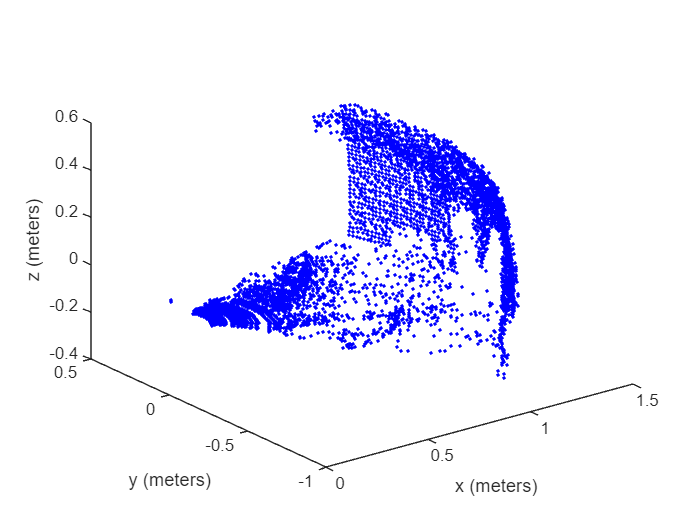

close all
%Load the raw data from the file
load raw_data.mat
data = [deg2rad(a(raw_data(:,1))),deg2rad(a(raw_data(:,2))),d(raw_data(:,3))];

%convert from polar to cartesian
[x,y,z] = sph2cart(data(:,1),data(:,2),data(:,3));

%Filter out noise data points
x_filtered = x;
y_filtered = y;
z_filtered = z;

% 54cm max, 43min
%values can be adjusted
x_filtered(x<0.4|x>0.6) = [NaN];
z_filtered(z<-0.1) = [NaN];

%plot unfiltered data only
figure()
axis equal
plot3(x,y,z,'.-b','LineStyle','none')
xlabel("x (meters)")
ylabel("y (meters)")
zlabel("z (meters)")

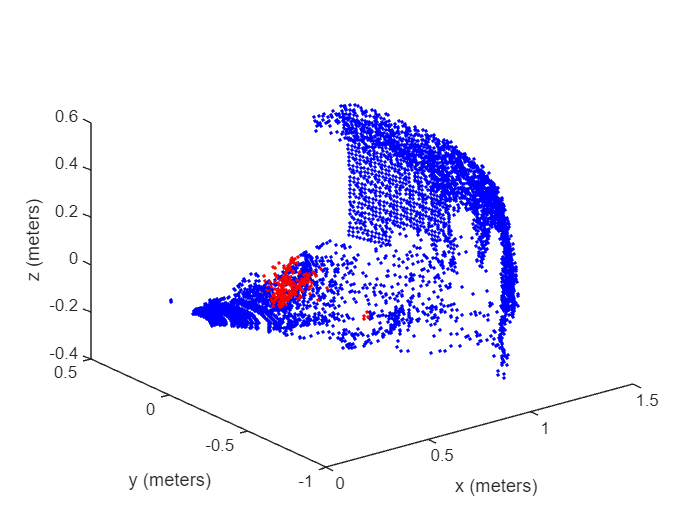



%plot unfiltered data as blue and filtered data as red
figure()
axis equal
plot3(x,y,z,'.-b','LineStyle','none')
xlabel("x (meters)")
ylabel("y (meters)")
zlabel("z (meters)")
hold on
plot3(x_filtered, y_filtered, z_filtered, '.-r', 'LineStyle','none')

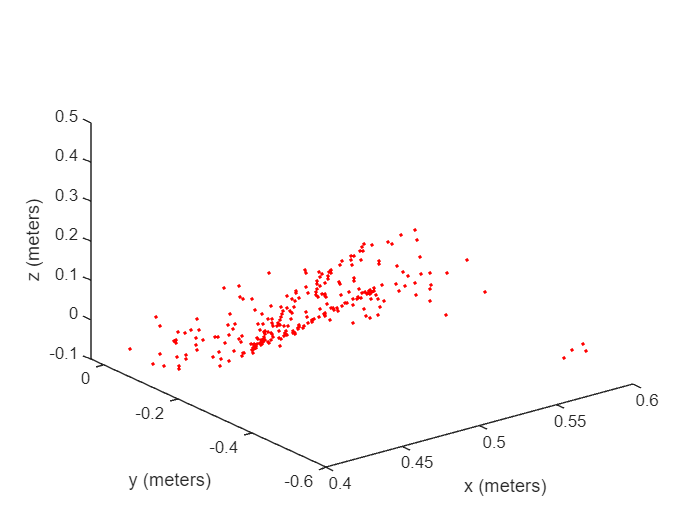


%filtered data only
figure()
axis equal
plot3(x_filtered,y_filtered,z_filtered,'.-r','LineStyle','none')
xlabel("x (meters)")
ylabel("y (meters)")
zlabel("z (meters)")
zlim([-0.1 0.5])


% x = x - 0.2;
% z = z - 0.2;

%Rotation method that doesnt seem to work at the moment:
% theta = 90;
% x = x;
% y = x.*cos(theta) - z.*sin(theta);
% z = y.*sin(theta) + z.*cos(theta);

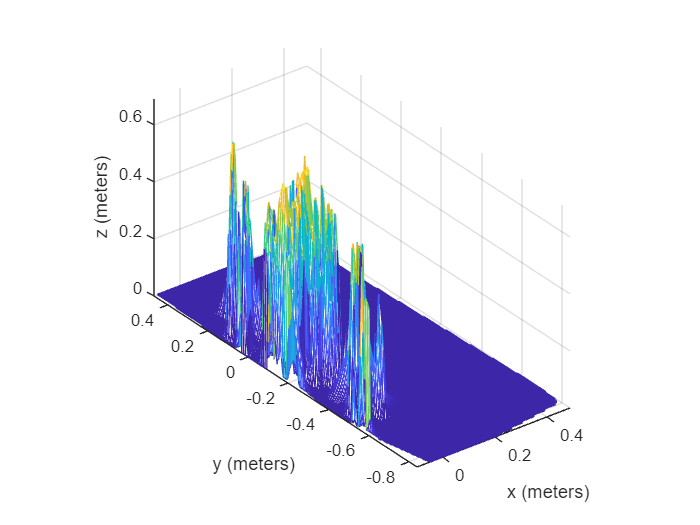

%Prepare data for plotting - other method
%Load the raw data from the file
load raw_data.mat
data = [deg2rad(a(raw_data(:,1))),deg2rad(a(raw_data(:,2))),d(raw_data(:,3))];

%convert from polar to cartesian (with z and x swapped)
[z,y,x] = sph2cart(data(:,1),data(:,2),data(:,3));

%Filter out noise data points
x_filtered = x;
y_filtered = y;
z_filtered = z;

z_filtered(z_filtered<0.35|z_filtered>0.7) = [0];
x_filtered(x_filtered<-0.1) = [0];

x = x_filtered;
z = z_filtered;

xlin = linspace(min(x), max(x), 150);
ylin = linspace(min(y), max(y), 150);
[X,Y] = meshgrid(xlin, ylin);
Z = griddata(x,y,z,X,Y,'natural');
%Z = griddata(x,y,z,X,Y,'v4');
%Z = griddata(x,y,z,X,Y,'natural');

%Plot
clf
figure()
mesh(X,Y,Z)
axis equal; hold on
%plot3(x,y,z,'.','MarkerSize',15)
xlabel('x (meters)')
ylabel('y (meters)')
zlabel('z (meters)')

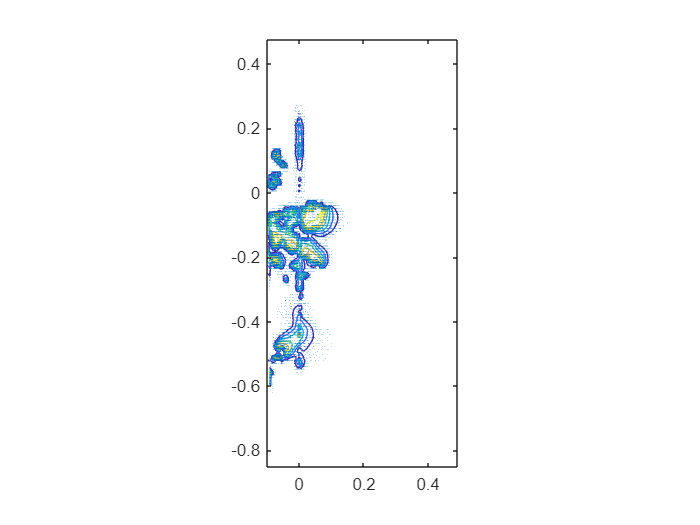


%Plot gradient and contour maps
figure()
contour(X,Y,Z)

[DX, DY] = gradient(Z); 
hold on
axis equal
quiver(X,Y,DX,DY)